clear variables;
% Read data file
location_name='AZ'; dataset_date='6-19';
pathname=['../../covid_state_hosp_data_' dataset_date '/'];


The call to `find_best_ICC_fit` returns the best parameters (`X`) as well as the data points used for the parameter estimation.

dt='05/05/2020'; n_pts=50;
[X_1,~,~,~,~] = find_best_ICC_fit(dt,n_pts,location_name,pathname);
dt='06/05/2020'; n_pts=14;
[X,~,~,~,~] = find_best_ICC_fit(dt,n_pts,location_name,pathname);

## Plots

The figures shows the smoothed data points used for the fit (stars), the actual data points (triangles), the smoothed data for the entire dataset, and the ICC curve that best fits the selected data points. 

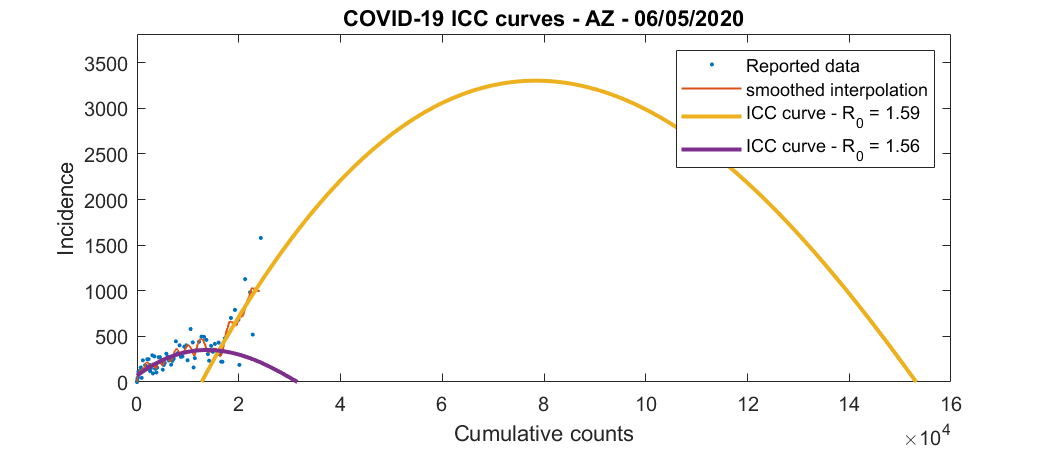

% Smooth and interpolate entire dataset
[~,~,~,C_o_raw,I_o_raw,~,~,C_o_ref,In_o_ref,~,~] = ...
    plot_ICC_curve(location_name,pathname,6,0,1,0,datenum('01/01/2020'),...
    datenum(dt));
figure(); set(gcf,'Position',[0 0 700 300]);
plot(C_o_raw,I_o_raw,'.'); hold on; plot(C_o_ref,In_o_ref,'-','LineWidth',1);
xlabel('Cumulative counts');
xx=1:X(3)/1000:X(3); yy=ICC(0,xx,X(1)^2,X(2)^2,X(3),X(4));
xx1=1:X_1(3)/1000:X_1(3); yy1=ICC(0,xx1,X_1(1)^2,X_1(2)^2,X_1(3),X_1(4));
plot(xx,yy,'-',xx1,yy1,'-','LineWidth',2);
hold off;
MI=round(1.05*max(yy));
ylim([0 1.1*MI]);
ylabel('Incidence'); title(['COVID-19 ICC curves - ' ...
    location_name ' - ' dt])
legend('Reported data','smoothed interpolation',...
    ['ICC curve - R_0 = ' num2str(round(100*X(1)^2/X(2)^2)/100)],...
    ['ICC curve - R_0 = ' num2str(round(100*X_1(1)^2/X_1(2)^2)/100)],...
    'Location','northeast')